data = sortrows([Age SpendingScores], 1);
x = data(:,1)';
y = data(:,2)';
% define optimization options
options = optimset('Display','iter','FunValCheck','on', ...
'MaxFunEvals',Inf,'MaxIter',Inf, ...
'TolFun',1e-6,'TolX',1e-6);
% define bounds for parameters
% a n b
paramslb = [-Inf 0 -Inf]; % lower bound
paramsub = [ Inf Inf Inf]; % upper bound
% define function that evaluates model given a vector
% of parameters (pp) and a matrix of x-values
modelfun = @(pp,xx) pp(1)*xx.^(-pp(2)) + pp(3);
% perform optimization for first seed
params0 = [1 1 1];
[paramsA,resnormA] = lsqcurvefit(modelfun,params0,x,y,paramslb,paramsub,options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          4          616223                      9.83e+03
     1          8          439113        9.02987       7.83e+03      
     2         12          438428             20       3.53e+04      
     3         16          345042              5       6.52e+03      
     4         20          328760        9.54753       6.26e+03      
     5         24          327516             20       6.24e+03      
     6         28          326854             40       6.23e+03      
     7         32          326320             80       6.22e+03      
     8         36          325952            160       6.22e+03      
     9         40          325728            320       6.21e+03      
    10         44          325603            640       6.21e+03      
    11         48          325537           1280       6.21e+03      
    12         52          32550

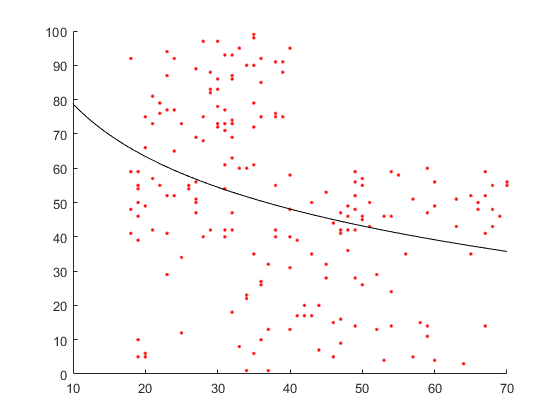


% visualize
figure; hold on;
scatter(x,y,'r.');
ax = axis;
xx = linspace(ax(1),ax(2),100);
hA = plot(xx,modelfun(paramsA,xx),'k-');

y_pred = modelfun(paramsA, x);
R2 = computeR2(y_pred, y)

R2 = 0.0987